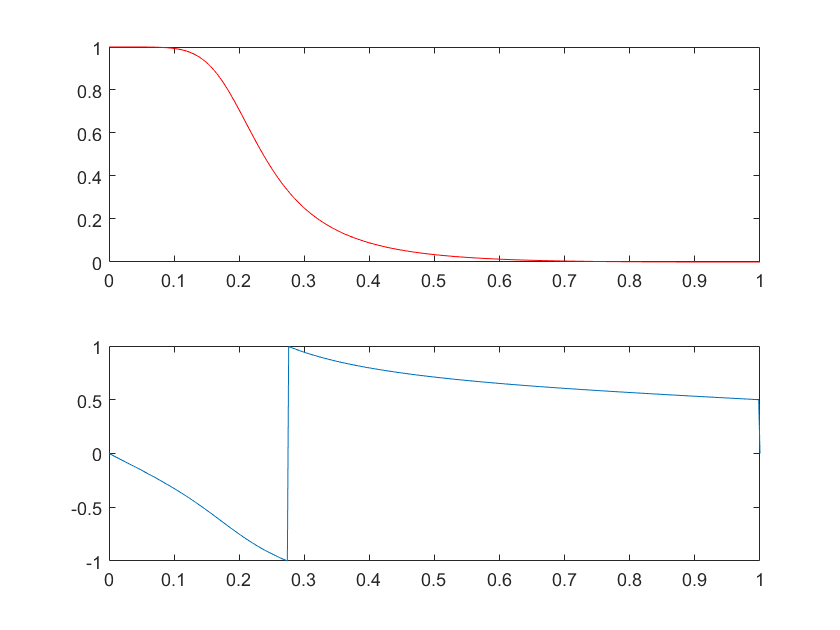

% frequency response function of difference equation
% 3rd order lowpass filter
b=[0.0181 0.0543 0.0543 0.0181];
a=[1 -1.76 1.1829 -0.2781];
% H=impz(b,a,500)
k=500;
n=0:k;
w=pi*n/k;
l=0:length(b)-1;
m=0:length(a)-1;
n=b*exp(-1j*(l'*w));
d=a*exp(-1j*(m'*w));
H=n./d;
mh=abs(H)';
a=angle(H)';
subplot(2,1,1)
plot(w/pi,mh,'r'); %hold on
subplot(2,1,2)
plot(w/pi,a/pi)